# Actin polymerization and physical models

# Part 1: From mental model to simulation

Matt Bovyn (mbovyn@uci.edu)

MCSB Bootcamp Dry 2019

Inspired by: [http://www.rpgroup.caltech.edu/mbl_physiology/code/cytoskeleton_manual.html](http://www.rpgroup.caltech.edu/mbl_physiology/code/cytoskeleton_manual.html)

## Actin

The actin cytoskeleton is a dynamic mesh, responsible for cell structure and movement

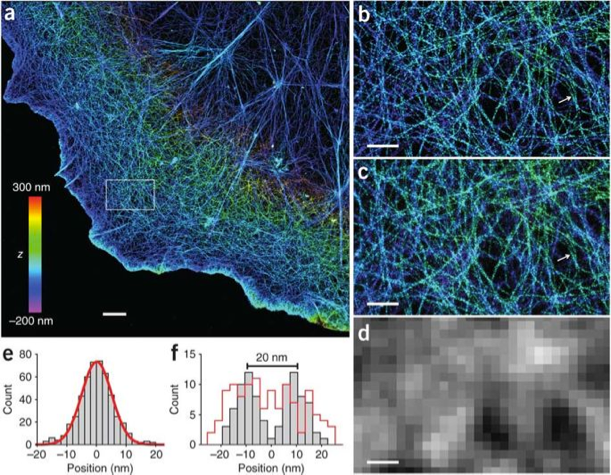

Xu ... Zhuang Nature Methods 2012 [https://www.nature.com/articles/nmeth.1841](https://www.nature.com/articles/nmeth.1841)

Examples of dynamic actin protrusions and motility:

Fritz-Laylin ... Mullins, eLife 2017 [https://elifesciences.org/articles/26990](https://elifesciences.org/articles/26990)

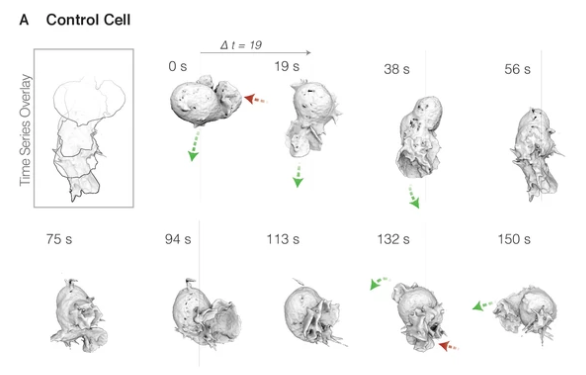

Actin (with only minimal helpers: salts, etc.) forms a double helical polymer

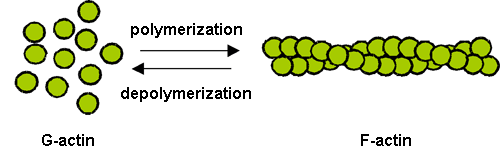

[http://www.spring8.or.jp/en/news_publications/press_release/2009/090122/](http://www.spring8.or.jp/en/news_publications/press_release/2009/090122/)

## How long is an actin filament?

Let's make a minimal model. We know:

1. Actin polymerizes - adds monomers

2. Actin depolymerizes - monomers fall off

3. This process is dynamic

For any one filament, length is a function of time. Let's make a simple model where monomers pop on and off with equal probability, then plot a stochastic trajectory

Your first task is to code up the simplest possible version of this: a for loop in which at each step you generate a random number (0 or 1) if 0, the size shrinks by one. If one, add one to the length. Keep track of how long the filament is with time and plot a trajectory.

% Your code here!

Should look something like this:

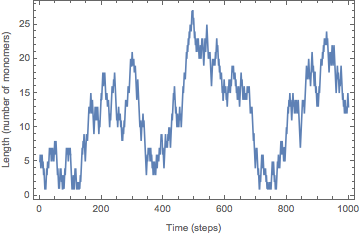

How long is it? Look at distribution of lengths. Do you recognize the distribution?

% Your code here!

Yours might (or might not) look something like this:

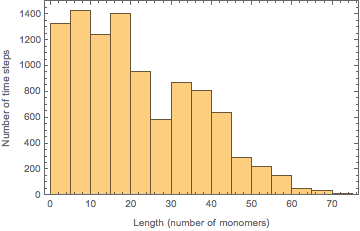

Is the distribution the same every time?

### A more physical model for length dynamics: fixed timestep monte carlo

If we are going to make a real model, we want output of length vs. time in seconds. For this, our model also needs to have physical parameters, which also have units.

We can phrase how often monomers go onto the filament as a rate (measured in inverse seconds), and the same for how often they fall off. We call them the on rate (kon) and the off rate (koff).

What do you think would happen if koff>kon? koff<kon?

#### Implementation

If a process has a rate of 5/s, what is the probability that event will happen in .1s? 1s? 10s?

We calculate p=r*dt. In our simulation, something either needs to happen or not happen though. How do we choose yes or no?

if rand()<.25
    disp('yes')
else
    disp('no')
end

no


Make a test of this system. Generate 10,000 random number with rand and make sure that the number of times rand() gives less than p where 0<p<1 is about p*10000

%Your code here!

Now let's write a version of our model of actin that two new things: fixed time steps and rates we can input (both kon and koff).

How big should your timestep be? We don't want more than one event to happen in one timestep. Let's say (1/min(kon,koff))*(1/100)

Start with what you had and give it a go. LIke before, you should output the length of the filament as a function of time (except time should now be in real seconds).

%Your code here!

Make some trajectories and play with the parameters. What can you learn about how long the filament is as a function of the on and off rates?

Using on and off rates of 10/s and 10/s, respectively, how long does it take to simulate 1 second of polymerization? What about .1/s and .1/s?

### Another approach to a more physical model: Gillespie / next event

Fixed timestep is one way of simulating a model like this. Another way is use a framework centered around the Gillespie algorithm. The Gillespie algorithm is a general way to simulate stochastic trajectories of chemical reactions when you know the rates of those reactions.

For Gillespie, we first need to be able to pull random numbers from an exponential distribution. How do we do that with Matlab?

exprnd(5)

ans = 1.8205

Test: what is the mean of 10,000 random numbers made with exprnd(5)?

%Your code here!

Then, to do a Gillespie simulation, we

1. choose initial length and time

2. Generate exponential random times from the distributions for each rate (kon and koff)

3. Choose the smaller of the two generated times. Increment our timestep by this time, then take the appropriate action (length+1, length-1)

%Your code here!

Compare your results at the same parameter sets you used above. Do you expect to see the same results?

Using on and off rates of 10/s and 10/s, respectively, how long does it take to simulate 1 second of polymerization using this method? What about .1/s and .1/s?

## Exploring the model

Using either fixed timestep monte carlo or Gillespie, answer the following questions:

So far we've measured the length of the actin filaments in number of monomers. Usually we measure length in micrometers (microns). How do we convert number of monomers to microns?

How does the mean length depend on the on and off rates? Is there more than one kon, koff that can give you a certain mean length?

#### Open ended questions

Say you measured actin lengths in the cell and found that their distribution was peaked (like a Gaussian/normal distribution). How would you modify the model to get a peaked distribution of lengths?

Say you wanted to visualize the model in physical space. How would you do it? Can you code up a rudimentary version?